y_min = -20;
y_max = 20;
dy = 5;
Ny = (y_max-y_min)/dy;
z_min = 5;
z_max = 30;
dz = 5;
Nz = (z_max-z_min)/dz;
x_val = 50;
y_val = linspace(y_min,y_max,Ny);
z_val = linspace(z_min,z_max,Nz);

X = x_val*ones(Ny*Nz,1);
Y = repmat(y_val,1, Nz)';
Z = repelem(z_val,Ny)';

[X1,Y1,Z1] = meshgrid(x_val,y_val,z_val);

If the wind is measured at height of h_r and has magnitude of w_r with direction phi_r with respect to the X axis, rotating towards Y axis, measured at (0,0,h_r)

W_vect = SurfaceWindProfile(wr,phi_wr,hr,h0,z_val);
s = size(z_val,2);
w_x = W_vect(1:s);
w_y = W_vect(s+1:2*s);
w_z = W_vect(2*s+1:end);

U = repelem(w_x,Ny);
V = repelem(w_y,Ny);
W = repelem(w_z,Ny);

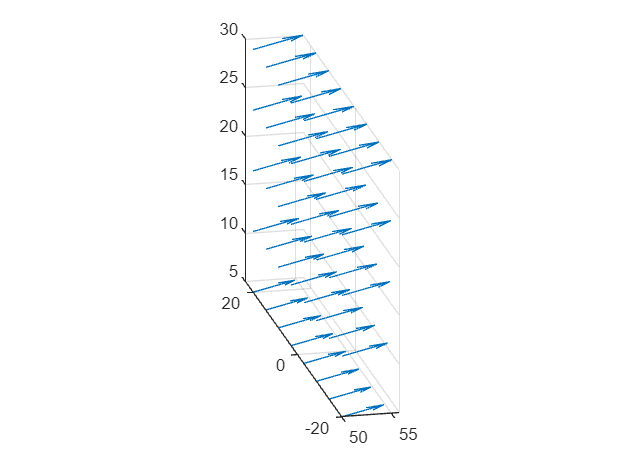

quiver3(X,Y,Z,U,V,W);
axis equal